Initial Setup

clear all
clc
close all

addpath('../code/Utils/rwt-master/src');
addpath('../code/Data');
addpath('../code/Recon');
addpath('../Human/MG85');

load('Data2_lat12.mat');

singledata = data(1,:);

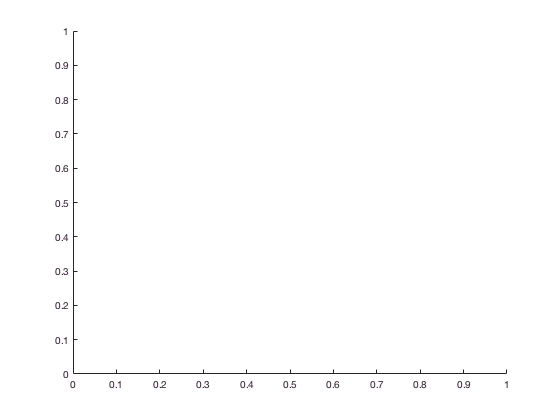

hold off

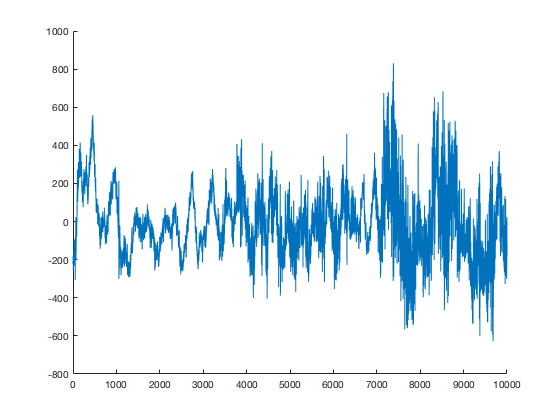

figure
hold on
plot(singledata(1:10000));
hold off

forder = 50;
lowband = 800;
highband = 8000;
sampl = 20000;
b = fir1(forder,[lowband/sampl*2,highband/sampl*2]);
singledataHPF = filter(b,1,singledata);


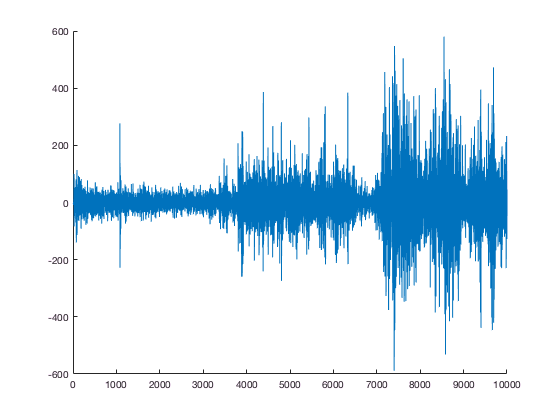

figure
hold on
plot(singledataHPF(1:10000));
hold off

%256 PCA domains

% d = designfilt('highpassfir', ...       % Response type
%         'StopbandFrequency',29, ...     % Frequency constraints
%         'PassbandFrequency',39, ...
%         'StopbandAttenuation',30, ...    % Magnitude constraints
%         'PassbandRipple',4, ...
%         'DesignMethod','kaiserwin', ...  % Design method
%         'ScalePassband',false, ...       % Design method options
%         'SampleRate',2000);               % Sample rate
% singledataHPF1 = filter(d,singledata);

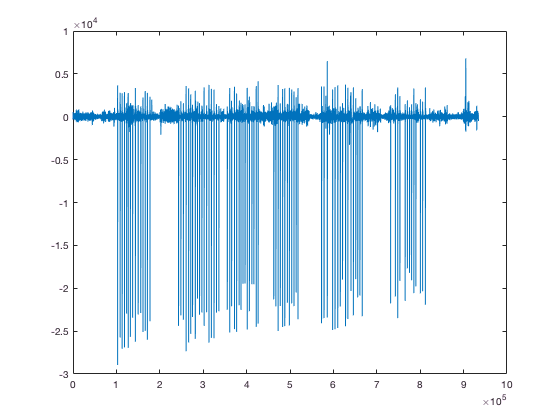

plot(singledata);

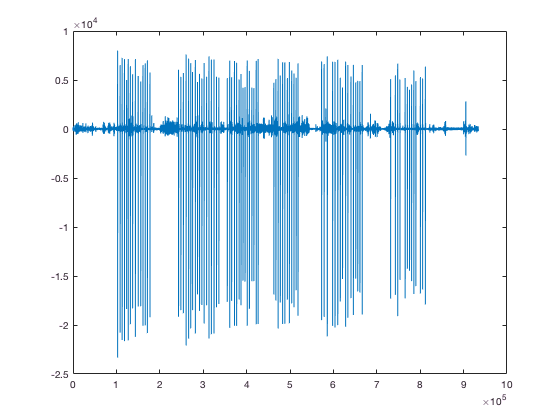

plot(singledataHPF);

% plot(singledataHPF1);

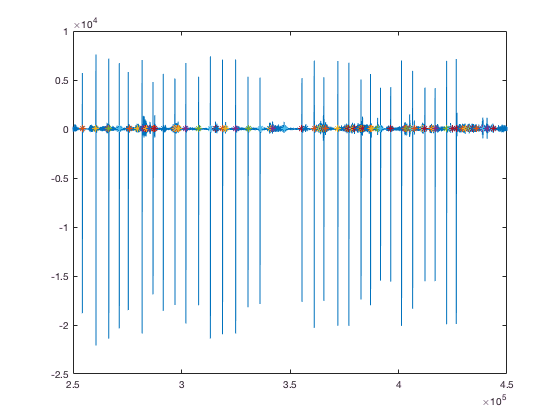

allLocs = getSpikeLocations(singledataHPF,1,20000,'threshGain',1);
hold off

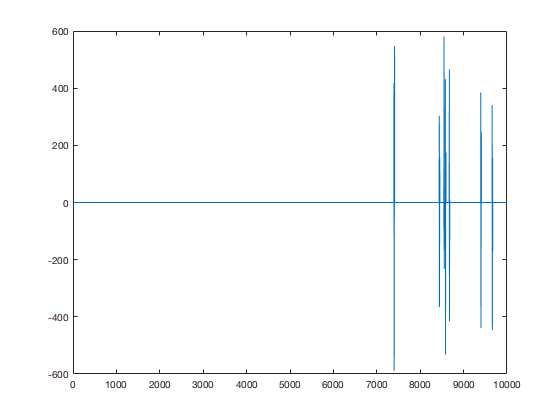

cleaneddataHPF = zeros(size(singledataHPF));

for i = 1:size(allLocs,2)
    cleaneddataHPF(1,allLocs(1,i)-5:allLocs(1,i)+10) = singledataHPF(1,allLocs(1,i)-5:allLocs(1,i)+10);
end
figure
plot (cleaneddataHPF(1:10000));

patchsize = 1000;
mfact = 0.8;
M = floor(patchsize*mfact);
fullN = size(cleaneddataHPF,2);
noofpatches = ceil(fullN/patchsize);
singledataHPF_recon1 = zeros(size(cleaneddataHPF));

Gaussian

% Phi = randn(M,patchsize);
% matrixNorm = Phi.'*Phi;
% matrixNorm = sqrt(diag(matrixNorm)).';
% Phi = Phi./repmat(matrixNorm, [M,1]);

subsampling matrix

D = dctmtx(patchsize);
iD = D^-1;
perm = randperm(patchsize);
Phi = iD(perm(1:M),:);

for i = 1:noofpatches
    starti = ((i-1)*patchsize)+1;
    endi = min(((i-1)*patchsize)+patchsize,fullN);
    if ((endi-starti+1)<patchsize)
        M = floor((endi-starti+1)*mfact);
        
        %Gaussian
%         Phi = randn(M,(endi-starti+1));
%         matrixNorm = Phi.'*Phi;
%         matrixNorm = sqrt(diag(matrixNorm)).';
%         Phi = Phi./repmat(matrixNorm, [M,1]);
        
        %Subsampling matrix
        D = dctmtx(endi-starti+1);
        iD = D^-1;
        perm = randperm(endi-starti+1);
        Phi = iD(perm(1:M),:);
    end
    shortdata = cleaneddataHPF (starti:endi);
    N = size(shortdata,2);
    K = nnz(shortdata);
    
    %Measurement
    y = Phi*dct(shortdata(1,:).'); %dct
    %y = Phi*mdwt(patch,h,L); %dwt
    %y = y + randn(size(y))*noise;
    
%     Recovery
%     alpha = OMP(y, Phi, K); % OMP
%     alpha = SP(y,Phi,K); % SP
%     alpha = FISTA(Phi,y); % FISTA
%     [alpha,~,~,~,~,~] = GPSR_Basic(y,Phi,lambda); %GPSR
%     alpha = ALM(Phi,y); % ALM
    alpha = FISTA(Phi,y); % FISTA
    
    x_recon = reshape(idct(alpha),N,1);
    singledataHPF_recon(starti:endi) = x_recon.';
    %patch_recon = reshape(midwt(alpha,h,L),n,n); % idwt
end

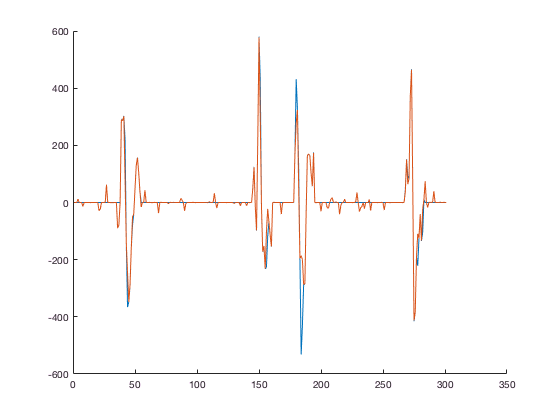

figure
hold on
plot(cleaneddataHPF(8400:8700));
plot(singledataHPF_recon(8400:8700));
hold off

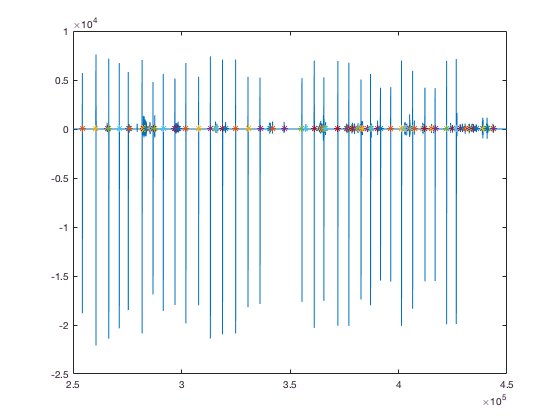

spikesHPF = getSpikeLocations(cleaneddataHPF,1,20000,'threshGain',1);

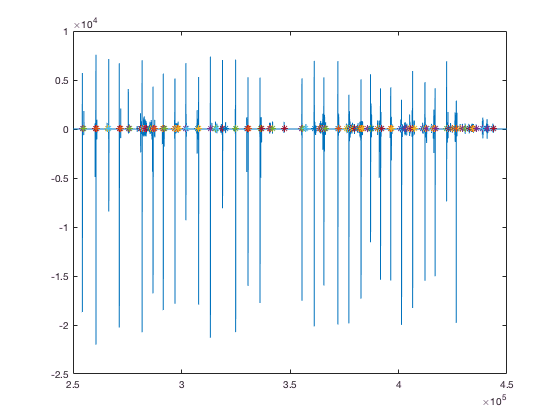

spikesHPF_recon = getSpikeLocations(singledataHPF_recon,1,20000,'threshGain',1);

disp(edr(spikesHPF, spikesHPF_recon, 1));

   290



disp(edr(cleaneddataHPF(1:20000), singledataHPF_recon(1:20000), 1));

   918



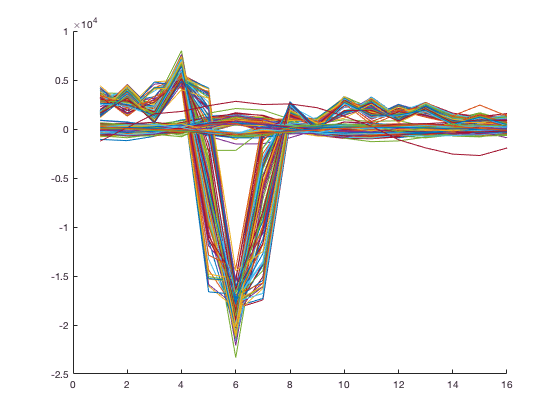

figure
hold on
for i = 1:size(spikesHPF,2)
    plot(singledataHPF(1,spikesHPF(1,i)-5:spikesHPF(1,i)+10));
end
hold off

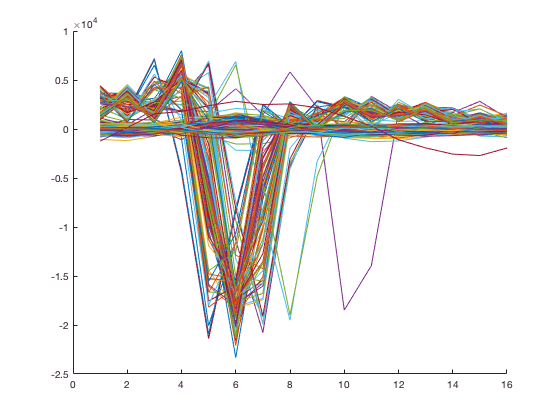


figure
hold on
for i = 1:size(spikesHPF_recon,2)
    plot(singledataHPF(1,spikesHPF_recon(1,i)-5:spikesHPF_recon(1,i)+10));
end
hold off